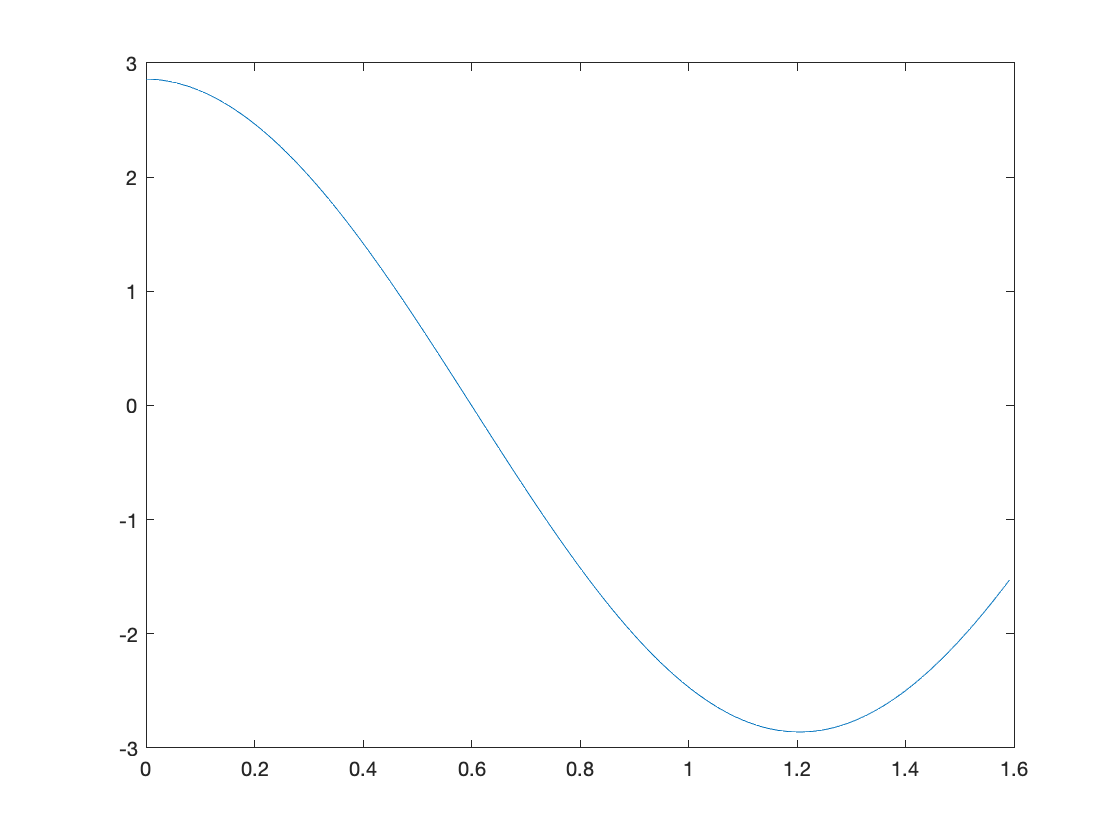

% ------------------------------------------------------
A     = 1.1; % fluorescence intensity units
omega = 2.6; % rad/s
A_0   = 0.01;

u=@(t) A*sin(omega*t)+A_0;

tArray = linspace(0,1.6,200);
uArray = u(tArray); % an array of samples of u
% ------------------------------------------------------

% analytical solutions (in real life, we might not know these)
dudtExact      =  A*omega*cos(omega*tArray);
du2dt2Exact    = -A*omega^2*sin(omega*tArray);
du3dt3Exact    = -A*omega^3*cos(omega*tArray);

%loop through noise size to detemine where 10% cutoff is
%give a variable name "z" to constant
%display(uObserved);

%figure;
%plot(tArray,uObserved, '+')
z = 1e-7;
uObserved = u(tArray) + z*randn(size(tArray));

%part 1
dudt = diff(uObserved)./diff(tArray);
du2dt2 = diff(dudt)./diff(tArray(1:end-1));
du3dt3 = diff(du2dt2)./diff(tArray(1:end-2));

plot(tArray(1:end-1), dudt)

q = linspace(0,0.1,100)

q =          0    0.0051    0.0101    0.0152    0.0202    0.0253    0.0303    0.0354    0.0404    0.0455    0.0505    0.0556    0.0606    0.0657    0.0707    0.0758    0.0808    0.0859    0.0909    0.0960    0.1010    0.1061    0.1111    0.1162    0.1212    0.1263    0.1313    0.1364    0.1414    0.1465    0.1515    0.1566    0.1616    0.1667    0.1717    0.1768    0.1818    0.1869    0.1919    0.1970    0.2020    0.2071    0.2121    0.2172    0.2222    0.2273    0.2323    0.2374    0.2424    0.2475


for i=1:100
    z = q(i);
    uObserved = u(tArray) + z*randn(size(tArray));
    dudt = diff(uObserved)./diff(tArray);
    du2dt2 = diff(dudt)./diff(tArray(1:end-1));
    du3dt3 = diff(du2dt2)./diff(tArray(1:end-2));
    diff1 = (dudt - dudtExact(1:end-1))./dudtExact(1:end-1);
    diff2 = (du2dt2 - du2dt2Exact(1:end-2))./du2dt2Exact(1:end-2);
    diff3 = (du3dt3 - du3dt3Exact(1:end-3))./du3dt3Exact(1:end-3);
        for j = 1:length(diff3)
            if abs(diff1(j))>0.1 || abs(diff2(j))>0.1 || abs(diff3(j))>0.1
                criticalError = z;
                i = 101;
                j = length(diff3)+1;
                break
            end
        end
end
criticalError

criticalError = 0.5000